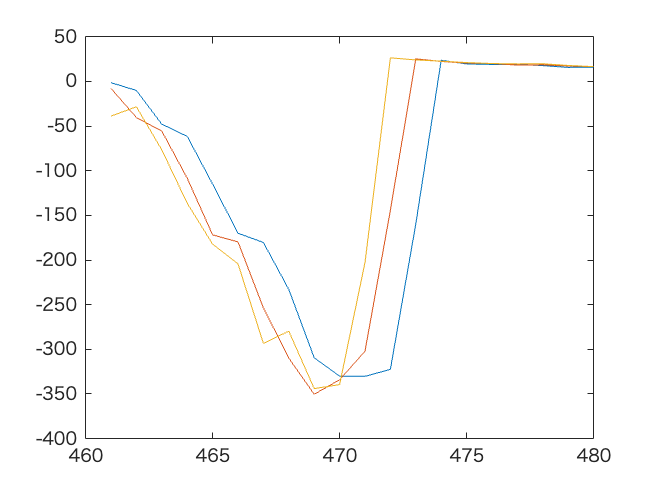

load('/Users/shinjirotakeda/Library/CloudStorage/GoogleDrive-takeda-shinjiro234@g.ecc.u-tokyo.ac.jp/マイドライブ/probedata/processed/240111022.mat','data2D','grid2D');
[~,xPointList] = get_axis_x_multi(grid2D,data2D);

Et_t1 = zeros(1,20);
t1 = 461:480;
m = 1;
for i = 61:80
    idxR = knnsearch(grid2D.rq(:,1),xPointList.r(i));
    idxZ = knnsearch(grid2D.zq(1,:).',xPointList.z(i));
    Et_t1(m) = mean(data2D.Et(max(1,idxR-3):min(idxR+3,numel(grid2D.rq(:,1))),max(1,idxZ-3):min(numel(grid2D.zq(1,:)),idxZ+3),i),'all');
    m = m+1;
end

load('/Users/shinjirotakeda/Library/CloudStorage/GoogleDrive-takeda-shinjiro234@g.ecc.u-tokyo.ac.jp/マイドライブ/probedata/processed/240111023.mat','data2D','grid2D');
[~,xPointList] = get_axis_x_multi(grid2D,data2D);

Et_t2 = zeros(1,20);
t2 = 461:480;
m = 1;
for i = 61:80
    idxR = knnsearch(grid2D.rq(:,1),xPointList.r(i));
    idxZ = knnsearch(grid2D.zq(1,:).',xPointList.z(i));
    Et_t2(m) = mean(data2D.Et(max(1,idxR-3):min(idxR+3,numel(grid2D.rq(:,1))),max(1,idxZ-3):min(numel(grid2D.zq(1,:)),idxZ+3),i),'all');
    m = m+1;
end

load('/Users/shinjirotakeda/Library/CloudStorage/GoogleDrive-takeda-shinjiro234@g.ecc.u-tokyo.ac.jp/マイドライブ/probedata/processed/240111024.mat','data2D','grid2D');
[~,xPointList] = get_axis_x_multi(grid2D,data2D);

Et_t3 = zeros(1,20);
t3 = 461:480;
m = 1;
for i = 61:80
    idxR = knnsearch(grid2D.rq(:,1),xPointList.r(i));
    idxZ = knnsearch(grid2D.zq(1,:).',xPointList.z(i));
    Et_t3(m) = mean(data2D.Et(max(1,idxR-3):min(idxR+3,numel(grid2D.rq(:,1))),max(1,idxZ-3):min(numel(grid2D.zq(1,:)),idxZ+3),i),'all');
    m = m+1;
end

figure;plot(t1,Et_t1);hold on;plot(t2,Et_t2);plot(t3,Et_t3);

Et_t = [Et_t1;Et_t2;Et_t3]

Et_t =    -1.3335  -10.1086  -47.8824  -61.4418 -114.9230 -170.0127 -180.3333 -232.9688 -309.4814 -330.0752 -330.3051 -322.4319 -159.5928   23.7051   19.6185   19.0628   19.1444   17.7557   15.7517   15.9690
   -7.8397  -40.4136  -55.6037 -108.3249 -171.8193 -179.7447 -253.6087 -309.9622 -350.3277 -334.1581 -302.1568 -144.2929   25.3012   22.4006   20.6280   20.1338   18.2941   18.6253   17.3060   16.6113
  -38.7820  -28.4242  -76.6189 -136.3955 -182.2004 -204.2875 -293.3471 -279.7015 -344.0081 -339.5660 -202.7454   26.4488   24.1301   22.6961   21.1475   20.0822   19.6829   19.8019   17.9217   16.5854


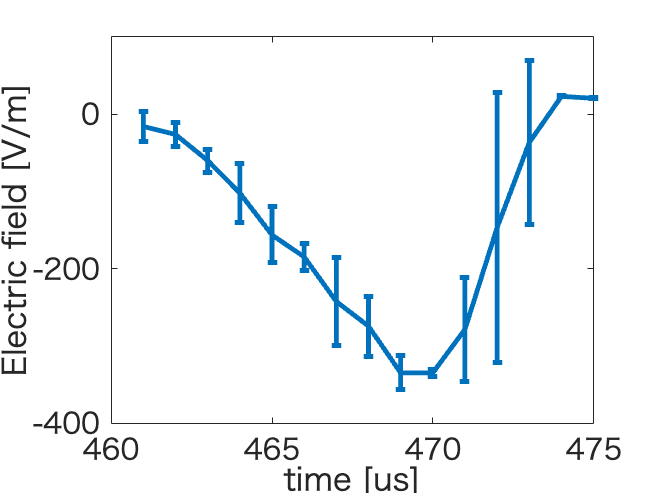

EtM = mean(Et_t,'omitmissing');
EtD = std(Et_t,'omitmissing');
figure;errorbar(t1,EtM,EtD,'LineWidth',3);
xlabel('time [us]');ylabel('Electric field [V/m]');
ax = gca; ax.FontSize = 18;
xlim([460 475]);yticks([-400 -200 0]);xticks([460 465 470 475]);